clear all;
% lidar=load(['C:\Users\sgrc-325\Desktop\git\lidar\lslidar.txt']);
% 讀取 CSV 檔案
% data = readtable(['C:\Users\sgrc-325\Desktop\git\lidar\LidarType_C_v5_0_2025-04-15-16-38_1Frame.csv']); %20hz 
% data = readtable(['C:\Users\sgrc-325\Desktop\git\lidar\LidarType_C_v5_0_2025-04-15-16-38_2Frame.csv']);
% data = readtable(['C:\Users\sgrc-325\Desktop\git\lidar\LidarType_C_v5_0_2025-04-15-16-38_200Frame.csv']);

data = readtable(['C:\Users\sgrc-325\Desktop\git\lidar\LidarType_C_v5_0_2025-04-16-11-58_1Frame.csv']); %5hz
% data = readtable(['C:\Users\sgrc-325\Desktop\git\lidar\LidarType_C_v5_0_2025-04-16-11-58_100Frame.csv']);

close all;
% 取出座標欄位
x = data.Points_X;
y = data.Points_Y;
z = data.Points_Z;
ang=data.H_angle;
dis=data.Distance1;
int=data.Intensity1;
ts=data.Timestamp_s;
tns=data.Timestamp_ns;

t=(ts-ts(1))+(tns-tns(1))*1e-9;
[N,~]=size(t);
f=N/t(end)/1000;
fprintf('time length: %.3f s\n',t(end));

time length: 0.200 s


fprintf('f: %.2f kHz\n',f);

f: 294.80 kHz


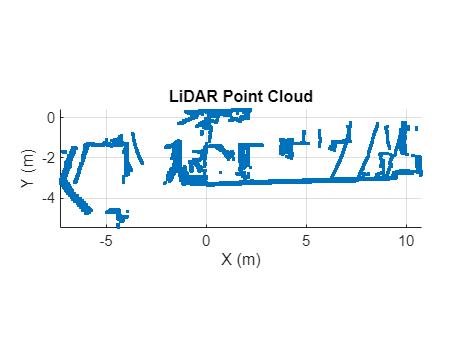



% 繪製 3D 點雲圖
figure(1);
plot3(x, y, z, '.');
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
title('LiDAR Point Cloud');
grid on;
axis equal;

view([0 90])

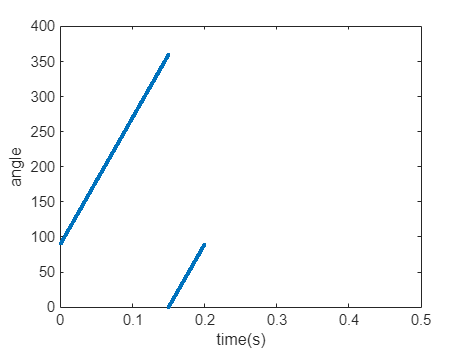


figure(2)
plot(t,ang,'.')
xlim([0 0.5])
xlabel('time(s)');
ylabel('angle');